close all;
clearvars;
clc;

## Load test image

img = imread('textureCell.tif');

## Display Image

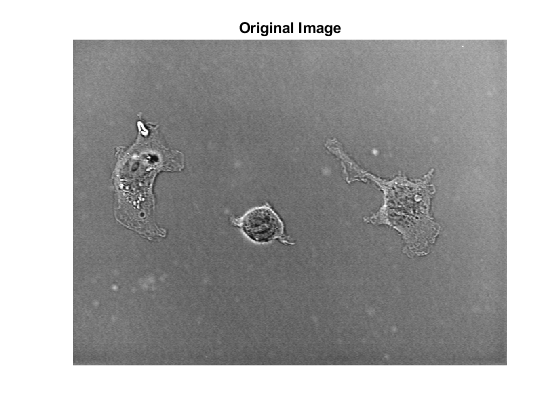

%h = figure('WindowStyle', 'docked');
imshow(img);
title('Original Image');


% Processing chain

## Process image

processedImg = processCellImage(img);

## Show figure

Input vs output

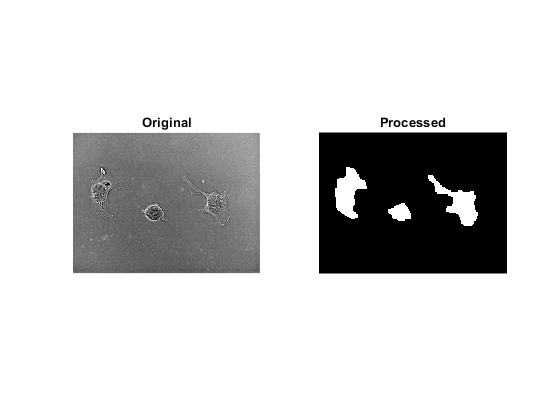

figure('WindowStyle','docked');
subplot(1,2,1)
imshow(img, [])
title Original
subplot(1,2,2)
imshow(processedImg, [])
title Processed

## Detect # of cells

s = regionprops(processedImg,'centroid', 'Area');

% Ignore small residues
idxToRemove = [];
for i = 1:length(s)
    if s(i).Area < 50
        idxToRemove = [idxToRemove i];
    end
end
s(idxToRemove) = [];

% Show number of detected cells
disp([num2str(length(s)) ' cells were found'])

3 cells were found


## Show figure

Input vs output

figure('WindowStyle','docked');
subplot(1,2,1)
imshow(img, [])
title Original
subplot(1,2,2)
imshow(processedImg, [])
title Processed

## Detect # of cells

s = regionprops(processedImg,'centroid', 'Area');

% Ignore small residues
idxToRemove = [];
for i = 1:length(s)
    if s(i).Area < 50
        idxToRemove = [idxToRemove i];
    end
end
s(idxToRemove) = [];

% Show number of detected cells
disp([num2str(length(s)) ' cells were found'])

3 cells were found
